% Resolução de Equações diferenciais com valores/parametros iniciais
%f(x) = -2xy^2

[t,y]=ode45(@odefun,[1 2],[1]);
[t,y]

ans =     1.0000    1.0000
    1.0250    0.9518
    1.0500    0.9070
    1.0750    0.8653
    1.1000    0.8264
    1.1250    0.7901
    1.1500    0.7561
    1.1750    0.7243
    1.2000    0.6944
    1.2250    0.6664
    1.2500    0.6400
    1.2750    0.6151
    1.3000    0.5917
    1.3250    0.5696
    1.3500    0.5487


function ydot=odefun(t,y)
ydot=-2*t*y^2;
end

Gráfico

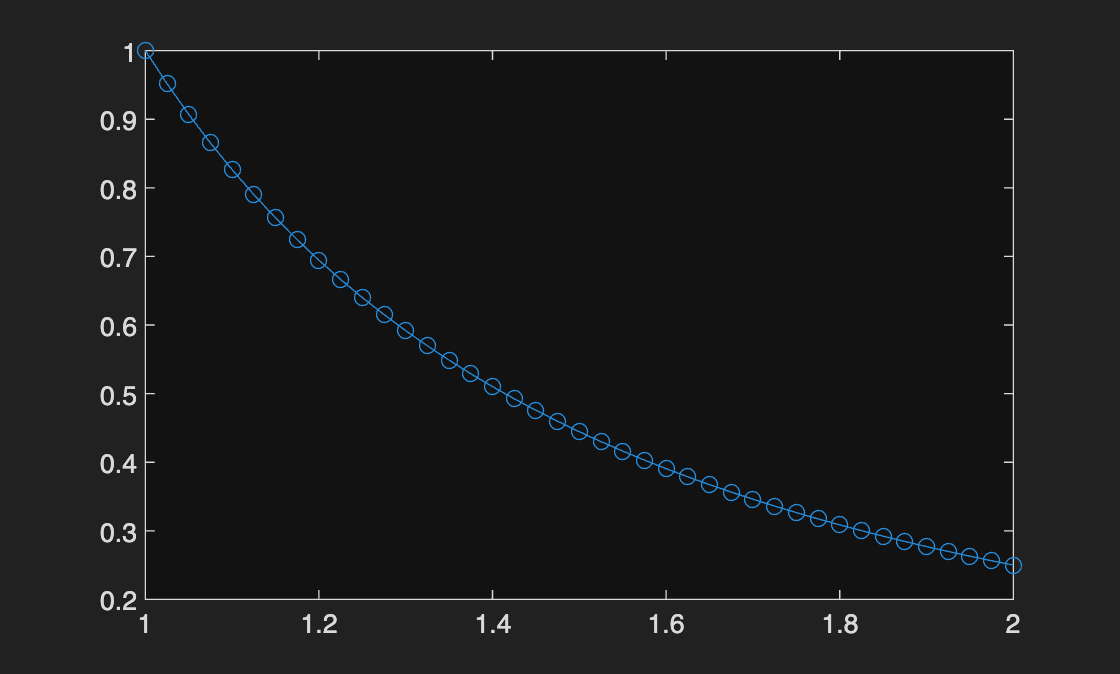

op = odeset('OutputFcn',@odeplot);
% Solve the ODE with the specified options and plot the results
[t, y] = ode45(@odefun, [1 2], [1], op);


y1 = fzero(@(x) x-1-0.5*(-2*1.5*x^2),1)

y1 = 0.5486

[t,y]=ode45(@odefun1,[1 1.5 2],[1]);
[t,y]

ans =     1.0000    1.0000
    1.5000    0.4444
    2.0000    0.2500


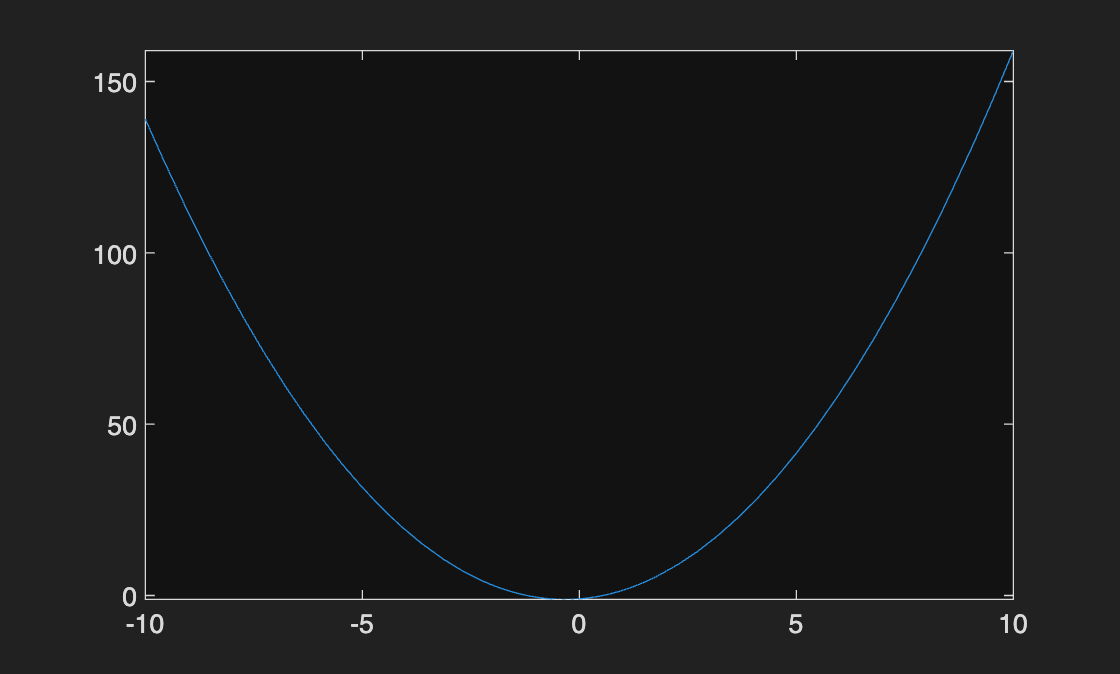


function ydot=odefun1(t,y)
ydot=-2*t*y^2;
end




fplot(@(x)  x-1-0.5*(-2*1.5*x^2), [-10,10])

Sistema de Equações

tspan = [0:5:20];
y0 = [0 0.25];
[t,y] = ode45(@volpol, tspan, y0);
[t,y] %para ver a solucao em formato tabela

ans =          0         0    0.2500
    5.0000   -1.6082    0.1432
   10.0000   -0.0948   -2.2627
   15.0000    1.8178   -0.5619
   20.0000    0.0813    2.2548


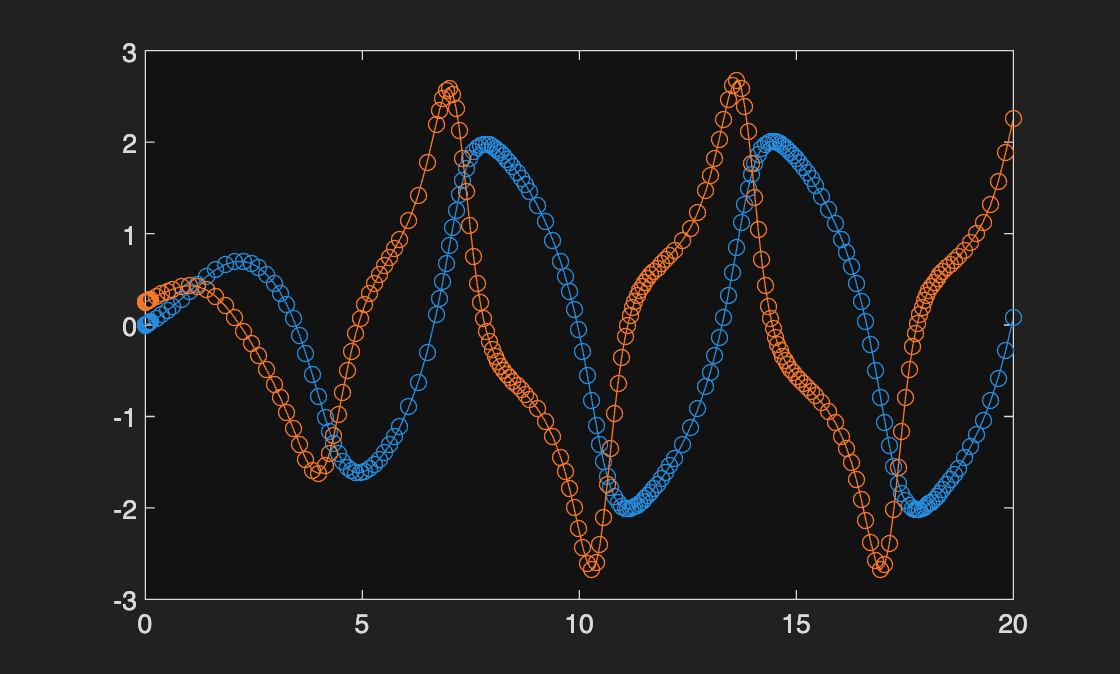


%funcao
function ydot=volpol(t,y)
ydot(1)=y(2);
ydot(2)=y(2)*(1- y(1)^2) - y(1);
ydot=ydot';
end


tspan = [0 20];
y0 = [0 0.25];
ode45(@volpol1, tspan, y0)

%funcao
function ydot=volpol1(t,y)
ydot(1)=y(2);
ydot(2)=y(2)*(1- y(1)^2) - y(1);
ydot=ydot';
end


%funcao
function ydot=volpol2(t,y)
ydot(1)=-2*y(1)*y(3)+2*y(2);
ydot(2)=2*y(1)*y(3)-2*y(2);
ydot(3)=-2*y(1)*y(3)+2*y(2)-0.2*y(3);
ydot=ydot';
end


tspan = [0 1];
y0 = [0.5 0 0.5];
[t,y] = ode45(@volpol2, tspan, y0)

t =          0
    0.0001
    0.0002
    0.0003
    0.0004
    0.0009
    0.0014
    0.0019
    0.0024
    0.0049
    0.0074
    0.0099
    0.0125
    0.0250
    0.0376


y =     0.5000         0    0.5000
    0.4999    0.0001    0.4999
    0.4999    0.0001    0.4999
    0.4998    0.0002    0.4998
    0.4998    0.0002    0.4998
    0.4995    0.0005    0.4995
    0.4993    0.0007    0.4992
    0.4990    0.0010    0.4989
    0.4988    0.0012    0.4986
    0.4976    0.0024    0.4971
    0.4963    0.0037    0.4956
    0.4951    0.0049    0.4941
    0.4939    0.0061    0.4927
    0.4881    0.0119    0.4857
    0.4826    0.0174    0.4789


[t,y]  

ans =          0    0.5000         0    0.5000
    0.0001    0.4999    0.0001    0.4999
    0.0002    0.4999    0.0001    0.4999
    0.0003    0.4998    0.0002    0.4998
    0.0004    0.4998    0.0002    0.4998
    0.0009    0.4995    0.0005    0.4995
    0.0014    0.4993    0.0007    0.4992
    0.0019    0.4990    0.0010    0.4989
    0.0024    0.4988    0.0012    0.4986
    0.0049    0.4976    0.0024    0.4971
    0.0074    0.4963    0.0037    0.4956
    0.0099    0.4951    0.0049    0.4941
    0.0125    0.4939    0.0061    0.4927
    0.0250    0.4881    0.0119    0.4857
    0.0376    0.4826    0.0174    0.4789


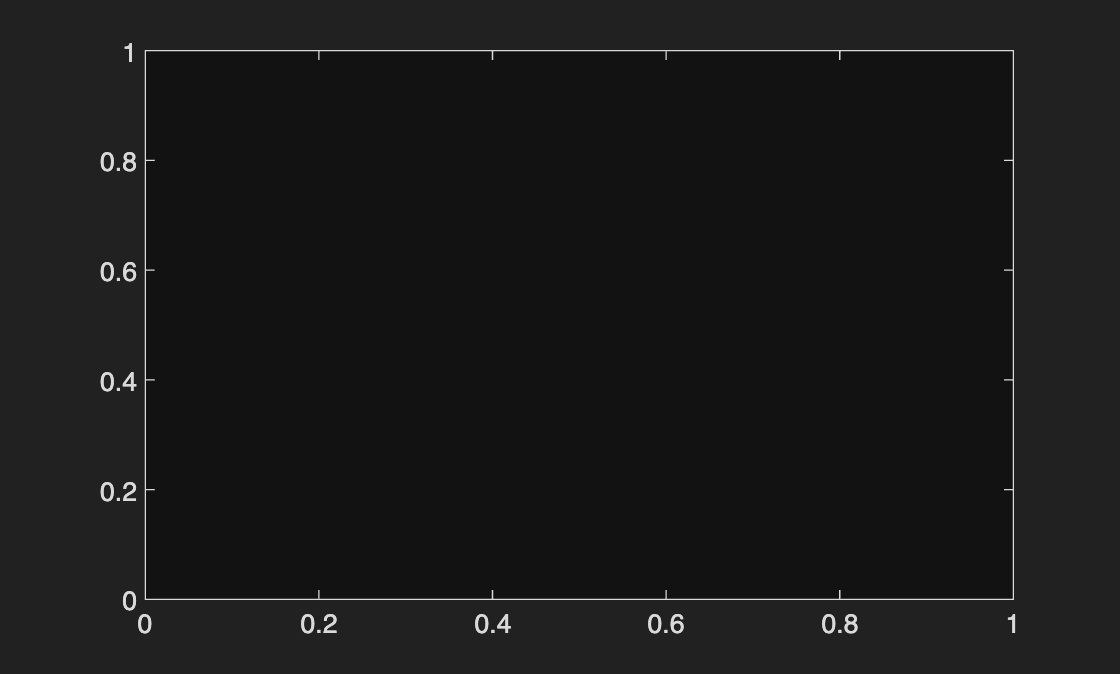

fplot(@(x1) @(x2) @(x3) -2*x1*x3+2*x2,[-10,10])

fplot(@(x1) @(x2) @(x3) 2*x1*x3-2*x2,[-10,10])

fplot(@(x1) @(x2) @(x3) -2*x1*x3+2*x2-0.2*x3,[-10,10])

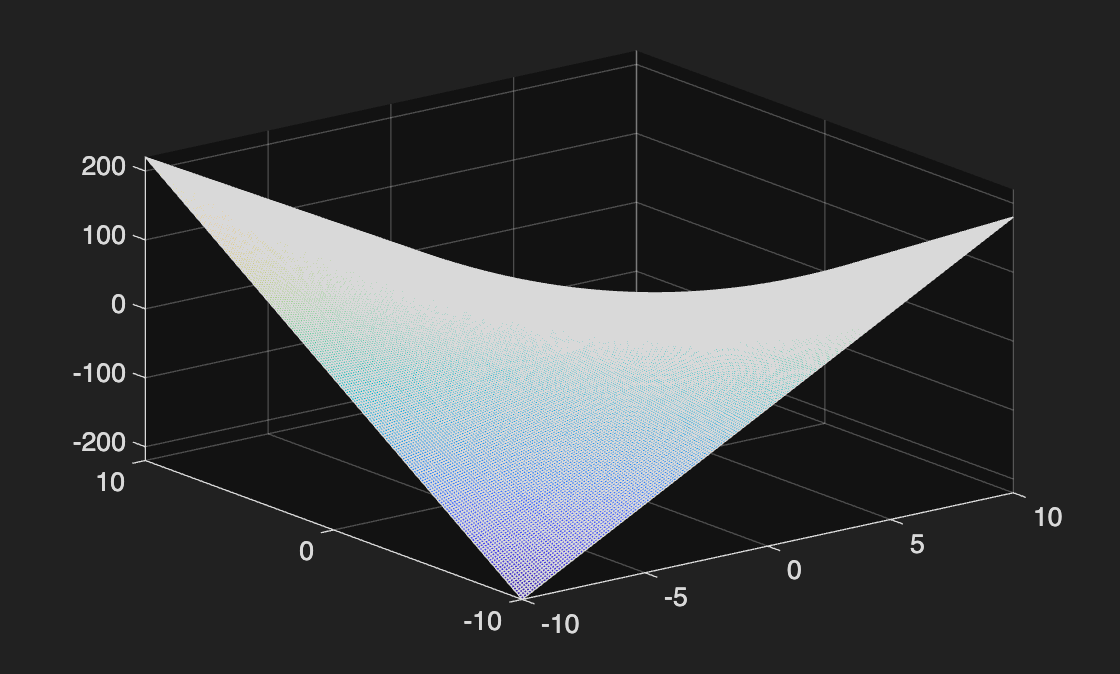

[x1, x3] = meshgrid(-10:0.1:10, -10:0.1:10);
f = -2*x1.*x3 + 2*x3;
surf(x1, x3, f)